ol

ol =   OL490Class with properties:

                   m: [1×1 OL490_SDK_Dll.OL490SdkLibrary]
            asmCyUSB: []
        asmOLIPlugin: []
         asmOL490Lib: []
         asmOL490SDK: []
    max_column_value: 40000
           gamma_lut: [11×2 double]
           classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Class'


cs

cs =   pr730Class with properties:

          ver: '6/15/2022'
      comPort: [1×1 rs232Class]
    connected: 1
     settings: '00000,FP-730-4,None,None,None,2 deg,Metric,Adaptive,500 msec,4xFast,1 cycles,2 deg,No Smart Dark,Standard Sensitivity,No Sync,20.00 Hz,5 nm'


ols

ols =   OL490Sim with properties:

          col_spec: [1024×401 double]
          speC_max: [1×1 SpectrumClass]
          speC_min: [1×1 SpectrumClass]
         reflC_min: [1×1 SpectrumClass]
         classpath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim'
     inputdatapath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim/spike_0615.mat'
    outputdatapath: 'C:\Users\wcc\Documents\GitHub\MIS_acquire\@OL490Sim/col_spec_0615.mat'


## Check accuracy of the forward model

Column 1000 is not modeled because 780 nm is excluded in the combs.

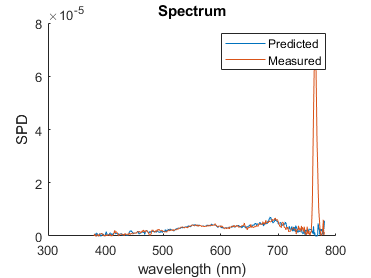

col_range  = [1000];

vec = OL490Class.VEC_multiple_peaks(col_range);

refl = ols.FWD_vec2reflC(vec);
spec = ols.FWD_vec2spdC(vec);

clf
hold on
spec.plot

ol.setColumn1024Gamma(vec)
mea = cs.measure;
mea.plot

legend('Predicted','Measured')